# 5G NR Synchronization Signal Capture Using Software-Defined Radio

This example shows how to use a software-defined radio (SDR) to capture a synchronization signal burst (SS burst). The example then analyzes the capture and attempts to identify the strongest synchronization signal block (SSB). Additionally, you can save the capture to a MAT-file for further analysis with the [NR Cell Search and MIB and SIB1 Recovery](docid:5g_ug#mw_a4db8282-8f25-4802-8b02-548bab69b7dd) example.

## Introduction

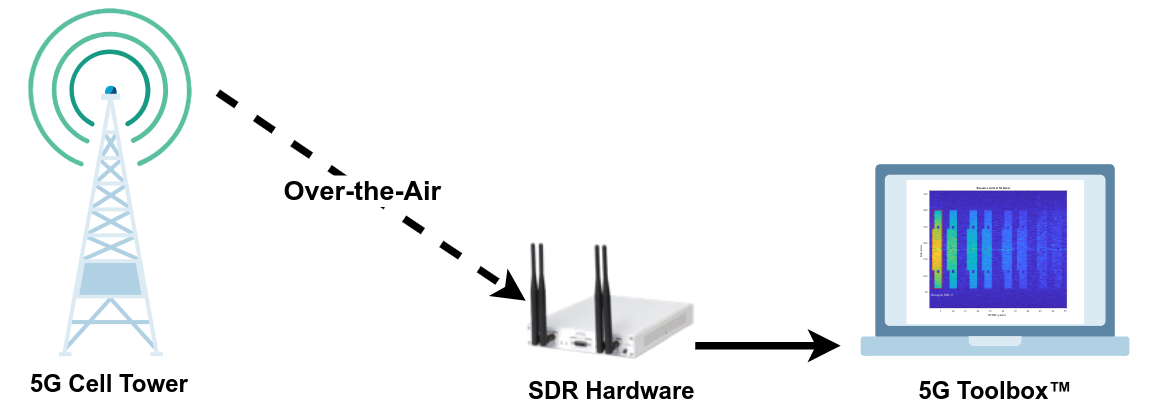

When user equipment (UE) performs initial synchronization procedures, it must scan over a set of predefined center frequencies searching for an SS burst. Once it detects an SSB, the UE identifies the cell ID and recovers the MIB and system information block type 1 (SIB1). 

The frequencies that a UE searches over are determined by the global synchronization channel numbers (GSCNs) defined in Table 5.4.3.3-1 of TS 38.101-1 [1]. This example shows how to select a GSCN value for your operating band of interest and calculate the center frequency. After the example determines the center frequency, it sets up the SDR receiver to capture a waveform at the specified frequency. You can specify additional parameters for the SDR receiver, such as gain, capture bandwidth, and capture antennas. After the SDR receiver captures a waveform, the example attempts to determine the location of the strongest SSB in the waveform. If the waveform contains an SSB and you want to perform a full recovery of the MIB and SIB1, you can save the waveform to a MAT-file for further analysis with the [NR Cell Search and MIB and SIB1 Recovery](docid:5g_ug#mw_a4db8282-8f25-4802-8b02-548bab69b7dd) example.

## Required Hardware and Software

This example uses SDRs supported by Wireless Testbench™ and Communication Toolbox™ support packages. This list provides information on which radios this example can use along with the required products.

- 300-Series USRP™ Radio or USRP X410 (requires Wireless Testbench™ and Wireless Testbench Support Package for NI™ USRP Radios). For more information, see [Install Support Package for NI USRP Radios](docid:wt_ug#mw_ef85a3b2-771b-408f-8f11-33225094dc75) and [Supported Radio Devices](docid:wt_gs#mw_74eb94c7-dcbc-40dc-8a56-cc7bc0124002).

- ADALM-PLUTO (requires Communications Toolbox Support Package for Analog Devices® ADALM-PLUTO Radio). For more information, see [ADALM-Pluto Radio](docid:comm_doccenter#mw_0e7ad01a-dc12-4f4d-bd42-54dc112c2e1d).

- USRP E310/E312 (requires Communications Toolbox Support Package for USRP™ Embedded Series Radio). For more information, see [USRP Embedded Series Radio](docid:comm_doccenter#mw_eaac0336-4b33-4e96-9c62-3fe07bf7e726).

- 200-Series USRP Radio (requires Communications Toolbox Support Package for USRP Radio). For more information, see [USRP Radio](docid:comm_doccenter#mw_de5fc03d-bc6e-471f-8da6-5e93b9b65012) and [Supported Hardware and Required Software](docid:usrpradio_ug#buzc7a6-1).

## Configure SDR Parameters

**Set Up SDR Receiver Object**

Specify the SDR's device name from the dropdown list along with the capture antenna configuration and radio gain.

If you are using an NI USRP hardware with Wireless Testbench, click **Update** to see your saved radio setup configuration name appear at the top of the dropdown list.

radioOptions = hSDRBase.getDeviceNameOptions; % Esta instrucción obtiene una lista de dispositivos SDR detectados por MATLAB con los paquetes soportados
rx = hSDRReceiver(radioOptions(10)) ; % Se crea el objeto receptor SDR utilizando el primer dispositivo detectado y configurado en la lista anterior. El objeto rx representa la radio que vas a usar para capturar datos.
antennaOptions = getAntennaOptions(rx); % Busca la lista de configuraciones de antena/dispositivos de entrada
rx.ChannelMapping = antennaOptions(1);% Qué canal se utiliza para recibir la señal :1 (RFA:RX2) o 2 (RFB:RX2)
rx.Gain = 50; % Define el nivel de ganancia del receptor RF en dB. Ganancia más alta = señal más fuerte (pero cuidado con sobresaturación).

**Specify Capture Center Frequency**

When deciding your capture center frequency, you have the option to speci

fy either a GSCN value or a custom center frequency. 

To determine a GSCN value, you must first determine the desired NR operating band that you want to capture. Use the table stored in the `FR1DLOperatingBand` property from the `hSynchronizationRasterInfo` class to inspect possible operating bands and their frequency ranges. Table 5.2-1 in TS 38.101-1 defines the table stored in the `FR1DLOperatingBand` property.

fr1BandInfo = hSynchronizationRasterInfo.FR1DLOperatingBand %Carga una tabla con todas las bandas de operación 5G NR disponibles en el rango FR1 (menos de 6 GHz)

fr1BandInfo = 49×2 table
           Lower Bound (MHz)    Upper Bound (MHz
           _________________    ________________

    n1           2110                 2170      
    n2           1930                 1990      
    n3           1805                 1880      
    n5            869                  894      
    n7           2620                 2690      
    n8            925                  960      
    n12           729                  746      
    n13           746                  756      
    n14           758                  768      
    n18           860                  875      
    n20           791                  821      
    n24          1525                 1559      
    n25          1930                 1995      
    n26           859                  894      
    n28           758                  803      
    n29           717                  728      


After you determine the band you would like to capture, specify it in the edit field below. 

The example extracts a structure containing possible GSCN values, subcarrier spacing of the SS burst, and the block pattern of the SS burst.  The information that is stored in the `SynchronizationRasterFR1` property of the `hSynchronizationRasterInfo` class comes from Table 5.4.3.3-1 in TS 38.101-1. 

syncRasterInfo = hSynchronizationRasterInfo.SynchronizationRasterFR1; 
band = "n78"; % Escoge la banda de operaciones 5G a explorar
bandRasterInfo = syncRasterInfo.(band) % Extrae toda la información relevante de esa banda: posibles GSCN, espaciamiento de subportadora (SCS), patrón de bloque de SS burst.

bandRasterInfo = struct with fields:
             SCS: 30
    BlockPattern: 'C'
            GSCN: [7711 7712 7713 7714 7715 7716 7717 7718 7719 7720 7721 7722 7723 7724 7725 7726 7727 7728 7729 7730 7731 7732 7733 7734 7735 7736 7737 7738 7739 7740 7741 7742 7743 7744 7745 7746 7747 7748 7749 7750 7751 7752 7753 … ] (1×341 double)


After selecting a GSCN value for the operating band of interest, specify the `GSCN` parameter in the edit field below. 

If you prefer to use a custom center frequency, select `useCenterFrequency` and enter your custom center frequency.

useCustomCenterFrequency = false;
GSCN = 7929;% Seleccionamos valor GSCN
if useCustomCenterFrequency
    rx.CenterFrequency = 3.55002e9; %#ok<*UNRCH>
else
    rx.CenterFrequency = hSynchronizationRasterInfo.gscn2frequency(GSCN); % convierte el GSCN seleccionado a la frecuencia real y la asigna al SDR
end

**Determine Subcarrier Spacing**

Based on the center frequency, the example determines the possible subcarrier spacing options (15 kHz or 30 kHz) that pertain to the operating band that the center frequency lies in.

Click **Update** to see the possible subcarrier spacing options and select a subcarrier spacing. The example uses the subcarrier spacing to analyze the captured waveform. 

scsOptions = hSynchronizationRasterInfo.getSCSOptions(rx.CenterFrequency);% Consulta la frecuencia central de rx para saber cuáles espaciados de subportadora se permiten en la banda asociada a tu frecuencia central ya definida.
scs =  scsOptions(1) ; %Selecciona el espacio de subportadora, El SCS define cómo procesarás la forma de onda, qué tasa de muestreo necesitas, y cómo configurarás la demodulación y búsqueda de sincronización.

**Determine Minimum Capture Sample Rate**

Use the [`nrOFDMInfo`](docid:5g_ref#mw_function_nrOFDMInfo) function to calculate the optimal capture sample rate for an SSB. Alternatively, specify a custom sample rate.

nrbSSB = 20; % Define el número de Resource Blocks (bloques de recurso físicos) que ocupa un bloque de sincronización SSB en 5G NR.
scsNumeric = double(extract(scs,digitsPattern)); % Extrae el valor del SCS y lo convierte a numero.
ofdmInfo = nrOFDMInfo(nrbSSB,scsNumeric); % Calcula y devuelve una estructura con información OFDM relevante
rx.SampleRate = 19900000; % Asigna la tasa de muestreo óptima calculada al SDR

**Initiate Waveform Capture**

Use the `framesPerCapture` parameter to specify the minimum number of full frames to capture.

framesPerCapture = 2; %Indica el número mínimo de fotogramas completos NR (cada uno de 10 ms) que deseas captar durante la adquisición.
captureDuration = seconds((framesPerCapture+1)*10e-3);

Begin the waveform acquisition.

waveform = capture(rx,captureDuration); % Invoca la función de adquisición y almacena la señal capturada en la variable waveform, utilizando la configuración definida para el SDR.
release(rx); % Finaliza y libera el recurso de SDR, permitiendo que otro proceso lo emplee o que puedas reconfigurarlo después.

## Locate Strongest SSB

Use the `findSSB` local function to identify if a valid SSB is present in the captured waveform. 

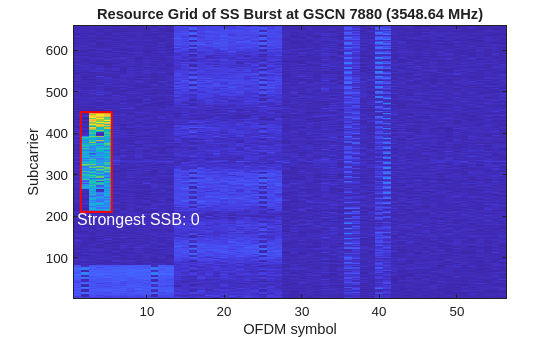

detectedSSB = findSSB(waveform,rx.CenterFrequency,scs,rx.SampleRate);% Esta sección toma la señal grabada y, usando el espaciado de subportadora, sample rate y frecuencia de captura, localiza automáticamente el SSB más fuerte.

## Further Exploration

**Save Waveform**

If the example detected a valid SSB in the captured waveform, save the waveform to a MAT-file for a more in-depth analysis with the [NR Cell Search and MIB and SIB1 Recovery](docid:5g_ug#mw_a4db8282-8f25-4802-8b02-548bab69b7dd) example.

Specify a filename for the MAT-file. The example appends the GSCN value and the capture date to the filename when saving the waveform.

fileNamePrefix = "capturedWaveform";
if detectedSSB
    saveWaveform(rx,waveform,scs,fileNamePrefix)
end

**Scan Multiple GSCNs**

Previously, the example captured only a single waveform and performed an initial analysis of it. The following code enables you to specify multiple GSCN values to scan over a set of center frequencies searching for valid SSBs. For each detected SSB, the example displays the SSB and saves the captured waveform to a MAT-file. 

Specify a vector of GSCN values for the example to scan over. To determine valid GSCN values, see the Specify Capture Center Frequency section.

GSCNs =[7853 7881]; % Cubre el GSCN encontrado y cercanos

Set the number of frames for the SDR receiver to capture.

framesPerCapture = 2;

Use the `scanGSCNs` local function to initiate a search for valid SSBs at the specified GSCNs. The function requires an `hSDRReceiver` object as one of the inputs. If an SDR receiver is not already set up, see the Set Up SDR Receiver Object section.

scanGSCNs(rx,GSCNs,framesPerCapture,fileNamePrefix);

No SSB Detected at GSCN 7853 (3509.76 MHz).
No SSB Detected at GSCN 7881 (3550.08 MHz).


## References

- 3GPP TS 38.101-1. "NR; User Equipment (UE) radio transmission and reception; Part 1: Range 1 Standalone" *3rd Generation Partnership Project; Technical Specification Group Radio Access Network*.

## Local Functions

These functions assist in locating valid SSBs. 

function scanGSCNs(rx,gscns,framesPerCapture,fileNamePrefix)
% SCANGSCNS uses the SDR receiver RX to capture a waveform at each GSCN in
% GSCNS. The functions analyzes each captured waveform for a valid SSB and
% subsequently saves the waveform to a MAT-file with the file name
% containing FILENAMEPREFIX. The duration of each captured waveform depends
% on FRAMESPERCAPTURE.
    captureDuration = seconds((framesPerCapture+1)*10e-3); %Calcula el tiempo de duración de la captura en segundos

    for gscn = gscns

        % Set up center frequency and sample rate based on GSCN
        rx.CenterFrequency = hSynchronizationRasterInfo.gscn2frequency(gscn); %Convierte el valor GSCN actual a una frecuencia central (en Hz) y la asigna al SDR
        scsOptions = hSynchronizationRasterInfo.getSCSOptions(rx.CenterFrequency); %Obtiene las posibles opciones de espaciamiento de subportadora (SCS) permitidas en esa frecuencia.
        for scs = scsOptions
            scsNumeric = double(extract(scs,digitsPattern));%Extrae el valor numérico del SCS a un formato double
            nrbSSB = 20; % Number of resource blocks in an SSB (esto es estándar en la mayoría de celdas 5G NR).
            ofdmInfo = nrOFDMInfo(nrbSSB,scsNumeric); %Calcula los parámetros OFDM (incluyendo SampleRate óptima) según el número de resource blocks y el SCS.
    
            % The receiver only captures a wide enough bandwidth to detect a
            % SSB. To find and decode the SIB1 the sample rate will need
            % increased.
            rx.SampleRate = ofdmInfo.SampleRate; %Asigna al SDR la SampleRate justificada por los parámetros OFDM calculados
    
            % Capture waveform
            waveform = capture(rx,captureDuration); %Realiza la captura de datos (samples de RF) durante el periodo calculado.
            release(rx); %Libera el objeto SDR para evitar bloqueos de hardware y preparar para la siguiente iteración.
    
            % Search for a valid SSB
            detectedSSB = findSSB(waveform,rx.CenterFrequency,scs,rx.SampleRate); % Analiza si la señal capturada contiene realmente un SSB válido según el estándar.
    
            if detectedSSB
                saveWaveform(rx,waveform,scs,fileNamePrefix)
            end
        end
    end
end

function saveWaveform(rx,waveform,scs,fileNamePrefix)
% SAVEWAVEFORM saves the WAVEFORM and other parameters to a MAT-file with
% the name containing FILENAMEPREFIX.
    % Initialize parameters that are to be saved to the MAT-file
    sampleRate = rx.SampleRate;
    fPhaseComp = rx.CenterFrequency;
    minChannelBW = hSynchronizationRasterInfo.getMinimumBandwidth(scs,rx.CenterFrequency);
    ssbBlockPattern = hSynchronizationRasterInfo.getBlockPattern(scs,rx.CenterFrequency);

    % Determine the number of SSBs in the SS burst
    if fPhaseComp > 3e9
        L_max = 8;
    else
        L_max = 4;
    end

    % Append GSCN and capture date to user supplied file name and save file
    gscn = hSynchronizationRasterInfo.frequency2gscn(rx.CenterFrequency);
    fileName = fileNamePrefix+"_"+gscn+string(datetime('now',Format='_yyyy_MM_dd'))+".mat";
    save(fileName,"waveform","sampleRate","fPhaseComp","minChannelBW","ssbBlockPattern","L_max")
end

function detectedSSB = findSSB(waveform,centerFrequency,scs,sampleRate)
% FINDSSB returns a logical value that depends on if WAVEFORM contains a
% valid SSB.
    ssbBlockPattern = hSynchronizationRasterInfo.getBlockPattern(scs,centerFrequency); % Obtiene el patrón de bloque SSB a buscar, según la numerología y frecuencia (por ejemplo, patrón 'C' para banda n78).
    scsNumeric = double(extract(scs,digitsPattern)); % Convierte el espaciado de subportadora a formato numérico (por ejemplo, 30 o 15 kHz).


    searchBW = 3*scsNumeric;
    displayFigure = false;
    [correctedWaveform,~,NID2] = hSSBurstFrequencyCorrect(waveform,ssbBlockPattern,sampleRate,searchBW,displayFigure); % Corrige la frecuencia de la señal para centrar el burst de sincronización. Extrae además el identificador secundario de la celda (NID2).



    % Create a reference grid for timing estimation 
    nrbSSB = 20;
    refGrid = zeros([nrbSSB*12 2]);
    refGrid(nrPSSIndices,2) = nrPSS(NID2);

    % Calculate timing offset and demodulate the grid
    % Calcula el desplazamiento temporal correcto (timing offset). Demodula la señal para extraer la grid OFDM de la ráfaga y se queda con símbolos centrales, donde está el SSB.
    nSlot = 0;
    timingOffset = nrTimingEstimate(correctedWaveform,nrbSSB,scsNumeric,nSlot,refGrid,SampleRate=sampleRate);
    correctedWaveform = correctedWaveform(1+timingOffset:end,:);
    rxGrid = nrOFDMDemodulate(correctedWaveform,nrbSSB,scsNumeric,nSlot,SampleRate=sampleRate);
    rxGrid = rxGrid(:,2:5,:);

    % Extract the received SSS symbols from the SS/PBCH block
    sssIndices = nrSSSIndices;
    sssRx = nrExtractResources(sssIndices,rxGrid);

    % Correlate received SSS symbols with each possible SSS sequence
    %Correlaciona el SSS recibido con todas las secuencias SSS posibles (336), buscando la que mayor energía tiene. Así estima el identificador principal de celda (NID1).
    sssEst = zeros(1,336);
    for NID1 = 0:335
        ncellid = (3*NID1) + NID2;
        sssRef = nrSSS(ncellid);
        sssEst(NID1+1) = sum(abs(mean(sssRx .* conj(sssRef),1)).^2);
    end

    % Determine NID1 by finding the strongest correlation
    NID1 = find(sssEst==max(sssEst)) - 1;

    % Form overall cell identity from estimated NID1 and NID2
    ncellid = (3*NID1) + NID2;

    % Calculate PBCH DM-RS indices
    dmrsIndices = nrPBCHDMRSIndices(ncellid);

    % Perform channel estimation using DM-RS symbols for each possible
    % DM-RS sequence and estimate the SNR
    dmrsEst = zeros(1,8);
    for ibar_SSB = 0:7
        refGrid = zeros([240 4]);
        refGrid(dmrsIndices) = nrPBCHDMRS(ncellid,ibar_SSB);
        [hest,nest] = nrChannelEstimate(rxGrid,refGrid,'AveragingWindow',[0 1]);
        dmrsEst(ibar_SSB+1) = 10*log10(mean(abs(hest(:).^2)) / nest);
    end

    % Record ibar_SSB for the highest SNR
    ibar_SSB = find(dmrsEst==max(dmrsEst)) - 1;

    % Channel Estimation using PBCH DM-RS and SSS
    refGrid = zeros([nrbSSB*12 4]);
    refGrid(dmrsIndices) = nrPBCHDMRS(ncellid,ibar_SSB);
    refGrid(sssIndices) = nrSSS(ncellid);
    [hest,nest] = nrChannelEstimate(rxGrid,refGrid,'AveragingWindow',[0 1]);

    % Extract the received PBCH symbols from the SS/PBCH block
    [pbchIndices,pbchIndicesInfo] = nrPBCHIndices(ncellid);
    pbchRx = nrExtractResources(pbchIndices,rxGrid);

    % Configure 'v' for PBCH scrambling according to TS 38.211 Section
    % 7.3.3.1 'v' is also the 2 LSBs of the SS/PBCH block index for
    % L_max=4, or the 3 LSBs for L_max=8 or 64.
    if centerFrequency <= 3e9
        L_max = 4;
        v = mod(ibar_SSB,L_max);
    else
        L_max = 8;
        v = ibar_SSB;
    end
    ssbIndex = v;

    % PBCH equalization and CSI calculation
    % Ecualiza los símbolos PBCH usando MMSE, calcula CSI, y decodifica los bits PBCH. 
    % Aplica error correction (polar coding) y verifica si la decodificación pasa el CRC, lo cual indica validez del burst SSB/MIB.
    pbchHest = nrExtractResources(pbchIndices,hest);
    [pbchEq,csi] = nrEqualizeMMSE(pbchRx,pbchHest,nest);
    Qm = pbchIndicesInfo.G / pbchIndicesInfo.Gd;
    csi = repmat(csi.',Qm,1);
    csi = reshape(csi,[],1);

    % PBCH demodulation
    pbchBits = nrPBCHDecode(pbchEq,ncellid,v,nest);

    % Apply CSI
    pbchBits = pbchBits .* csi;

    % Perform BCH decoding
    polarListLength = 8;
    [~,crcBCH] = nrBCHDecode(pbchBits,polarListLength,L_max,ncellid);
    gscn = hSynchronizationRasterInfo.frequency2gscn(centerFrequency);

   % Si el burst SSB es válido (CRC correcto): 
   % Dibuja la grid de recursos, marca el burst SSB encontrado y devuelve detectedSSB = true.
    if crcBCH == 0
        % Plot grid and highlight strongest SSB
        demodRB = 55;
        rxGrid = nrOFDMDemodulate(correctedWaveform,demodRB,scsNumeric,nSlot,SampleRate=sampleRate);
        % Extract 4 symbols of grid if exists
        if size(rxGrid,2) < 56
            last = size(rxGrid,2);
        else
            last = 14*4;
        end
        figure;imagesc(abs(rxGrid(:,1:last,1))); axis xy
        xlabel('OFDM symbol'); ylabel('Subcarrier');
        ttl = sprintf('Resource Grid of SS Burst at GSCN %d (%.2f MHz)',gscn,centerFrequency/1e6);
        title(ttl)
        ssbFreqOrigin = 12*(demodRB-nrbSSB)/2 + 1;
        startSymbol = 1;
        numSymbolsSSB = 4;
        rectangle('Position',[startSymbol+0.5 ssbFreqOrigin-0.5 numSymbolsSSB 12*nrbSSB],EdgeColor='r',LineWidth=1.5)
        str = sprintf('Strongest SSB: %d',ssbIndex);
        text(startSymbol,ssbFreqOrigin-nrbSSB,0,str,FontSize=12,Color='w');
        detectedSSB = true;
        drawnow
    else
        detectedSSB = false;
        fprintf("No SSB Detected at GSCN %d (%.2f MHz).\n",gscn,centerFrequency/1e6);
    end
end

*Copyright 2023 The MathWorks, Inc.*